syms L z A

F = A*z;
int(F,z,[-L/2 L/2])

$$ans = 0$$


F2 = A*z^2;
int(F2,z,[-L/2 L/2])

$$ans = \frac{A\,L^{3}}{12}$$

F3 = A*z^3;
int(F3,z,[-L/2 L/2])

$$ans = 0$$

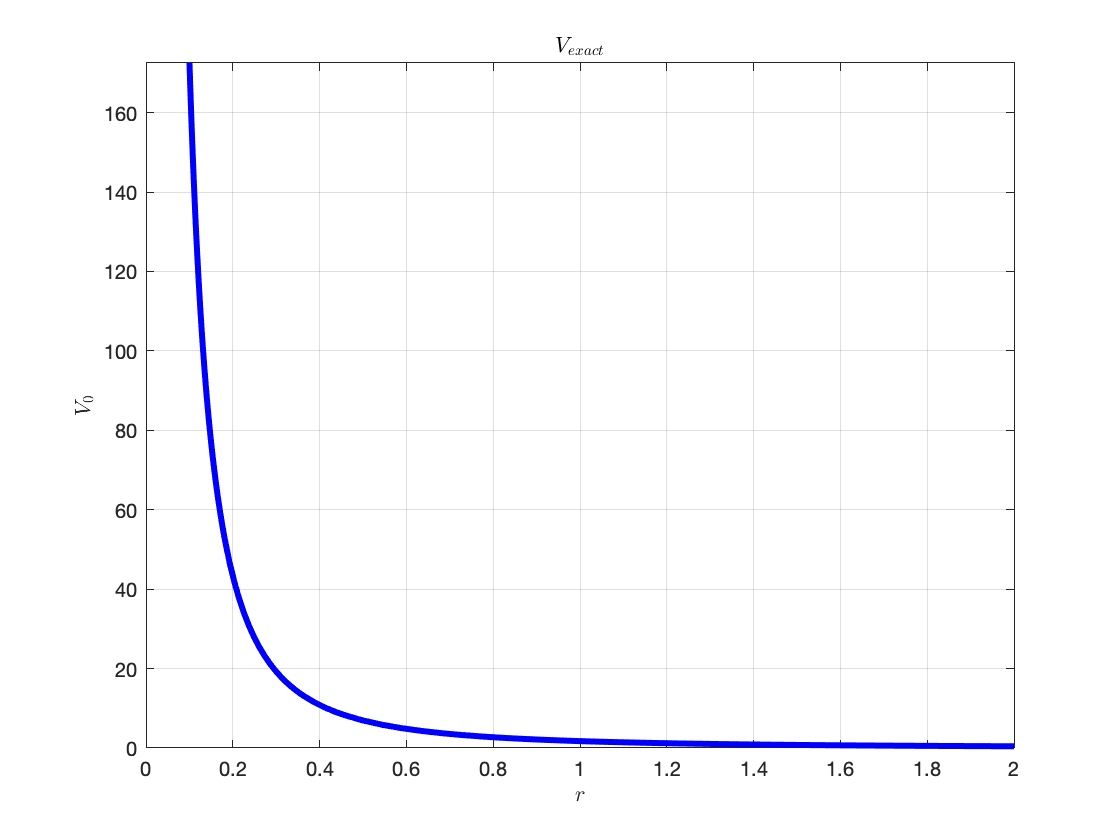

syms V r epsilon_0
assume(r>0)
q = 1;
V_0 = (4*pi*epsilon_0)/q;

x1 = 0;
y1 = r/sqrt(3);
z1 = 0;
R1 = sym(r*sqrt((x1+y1+z1)^2));

x2 = r/sqrt(3);
y2 = 2*r/sqrt(3);
z2 = 0;
R2 = sym(r*sqrt((x2+y2+z2)^2));

x3 = sym(r/sqrt(3));
y3 = sym(r/sqrt(3));
z3 = sym(r/sqrt(3));
R3 = sym(r*sqrt((x3+y3+z3)^2));

V = (1/(4*pi*epsilon_0))*(q/R1 + q/R2 - q/R3);
V = V_0*V;
V = matlabFunction(V);
fplot(V,'LineWidth',3,'Color','b','DisplayName','V_approx')
title('$V_{exact}$','Interpreter','latex')
xlabel('$r$','Interpreter','latex')
ylabel('$V_{0}$','Interpreter','latex')
xlim([0 2])
%ylim([0 10])
grid on

syms r V epsilon_0
assume(r>0)
q = 1;
V_0 = (4*pi*epsilon_0)/q;
x = r/sqrt(3);
y = r/sqrt(3);
z = r/sqrt(3);

[phi, theta, r] = cart2sph(x,y,z)

$$phi = \frac{\pi }{4}$$

$$theta = \mathrm{atan}\left(\frac{\sqrt{2}}{2}\right)$$

$$r = r$$


V = V_0*(q/(4*pi*epsilon_0*r)+(q*cos(theta))/(2*pi*epsilon_0*r^2));
V = simplify(V)

$$V = \frac{3\,r+2\,\sqrt{6}}{3\,r^{2}}$$

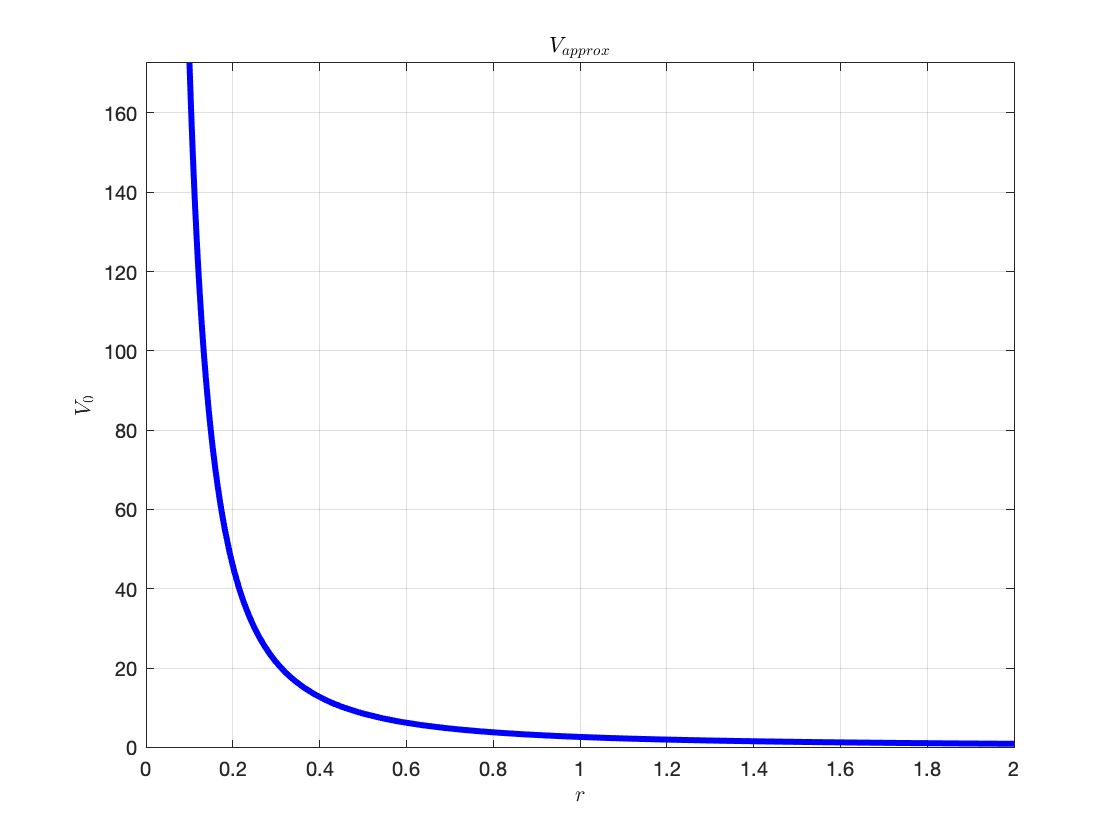

V = matlabFunction(V);
fplot(V,'LineWidth',3,'Color','b','DisplayName','V_approx')
title('$V_{approx}$','Interpreter','latex')
xlabel('$r$','Interpreter','latex')
ylabel('$V_{0}$','Interpreter','latex')
xlim([0 2])
%ylim([0 10])
grid on